% This tutorial takes an example cluster assignment that spans repeats or
% each column is a repeat/subject/bootstrap that has no temporal correspondence
% across the columns

% Notes: make sure this toolbox and subfolders is on the MATLAB path
% (https://www.mathworks.com/help/matlab/ref/addpath.html)

clear;close all;clc; % this just clears the workspace, command window and close all figures to start clean

% Load example data
load('./ExampleData/example_clusters_categorical.mat','example_clusters'); % Nnodes x Nrepeats
example_clusters = example_clusters(:,1:100);
input_check_HSB(example_clusters); % will produce an error if your input is problematic

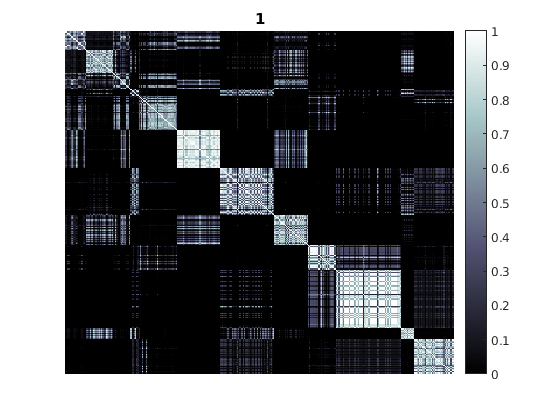

Paused. Press Any Key to Continue and CTRL+C to quit


%% Step 1: Generate a coassignment matrix that shows the frequency of coassignment across clusters
% N.B. can be used as input for hierarchicalConsensus() but it usually
% requires a lot of levels(columns)

C = coclassificationMatrix(example_clusters); % would be the same if you used sorted_clusters but the input needs to be double(sorted_clusters)
levels = 1:size(example_clusters,2); % replace if you have any meaningful value for the levels, e.g. the number of communities, the resolution parameter etc.

% sanity check: visualize the co-assignment matrix sorted by the assignment
% of each level, note that this is NOT your original matrix input to
% generate the community assignment but the frequency of coassignment of
% nodes


figure;
for k = 1:size(example_clusters,2)
    [~,sortid] =sort(example_clusters(:,k));
    imagesc(C(sortid,sortid));colormap(bone);
    colorbar;
    axis off;
    title(levels(k));
    
    disp('Paused. Press Any Key to Continue and CTRL+C to quit');
   
    pause;
    clf;
end


% You should see some kind of block organization.

%% Step 2: Visualize solution landscape
% use example_clusters instead of sorted_clusters here because we don't
% want zeros in the assignments

metric = 'zRand' ,% alternatives: NMI, VI, AMI (N.B. AMImax), zRand,Rand, aRand (case-insensitive) please see similarity_measures_HSB.m for details

metric = 'zRand'


tic
D = similarity_measures_HSB([example_clusters],metric); % calculate a similarity measure 
toc

Elapsed time is 0.204950 seconds.


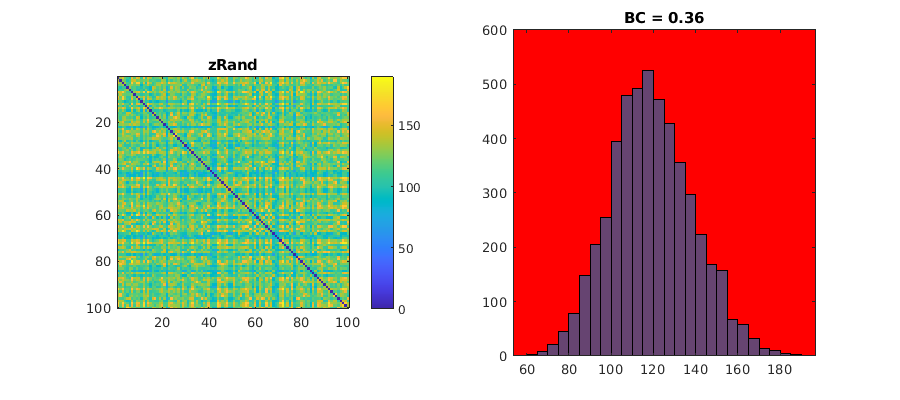


[BF,BC] = bimodalitycoeff(squareform(D)); % check for unimodal normal distribution or multimodal normal distribution

figure('position',[100 100 900 400]);
subplot(1,2,1);
imagesc(D);
axis square
title(metric)
colorbar;
subplot(1,2,2);
histogram(squareform(D))
title(sprintf('BC = %1.2f',BC));
% set axes background in green or red depending on BF
% - green for bimodality and red for non-bimodality
if BF
    set(gca, 'Color', 'g')
else
    set(gca, 'Color', 'r')
end

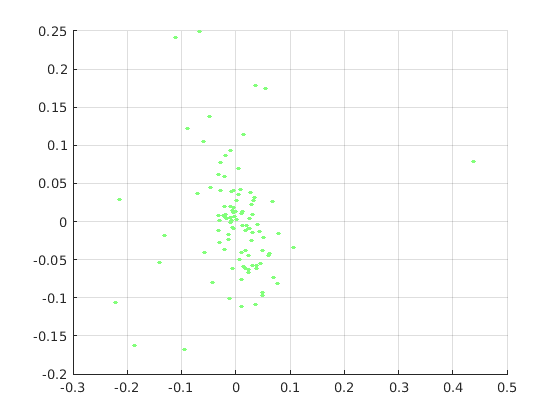


% convert to low-D representation
[x] = cmdscale(exp(-D),2); % take the exponential of the negative because cmdcale takes positive matrix only and larger D, not sure this is the best way to do it 
quality = ones(size(x,1),1); % Replace this with the quality of your algorithm if you have one, for example, modularity or log likelihood 
figure;
scatter(x(:,1),x(:,2),10,quality,'filled');colormap(jet); % the distance between points index their similarity and the color of the points indicate the quality function
grid on

xlabel('dim 1');
ylabel('dim 2')
% Conclusion: 
% if the histogram appear unimodal and the solutions appear in one good cluster in 2D with a clear peak of high quality then we can
% take the max quality partition, or find a consensus across the
% partitions, alternatively, we may consider doing clustering on the
% solution set or conclude that this particular set of solutions is
% unstable


%% Step 3: Sort the community numbers to match between the columns as best as possible
% N.B.: this might take a while and may not produce the same results each time unless random seed is fixed because it is not ordered
rng(1);
minsize = 2;
tic
sorted_clusters  = postprocess_categorical_multilayer(example_clusters);  % sort across level to have some consistency across columns
toc

Elapsed time is 3.505836 seconds.


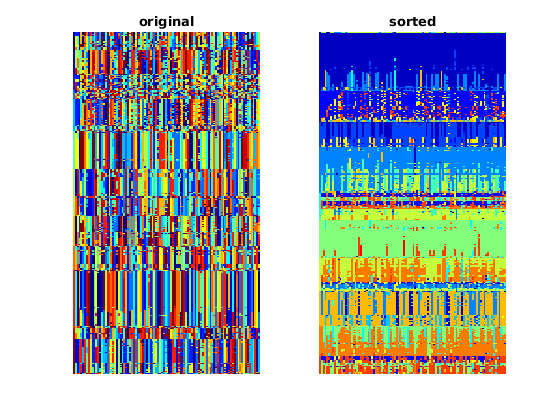

sorted_clusters = remove_singleton(sorted_clusters,minsize); % remove communities smaller than a size

% sanity check plot: you should see some consistency across columns
figure;
subplot(1,2,1);
imagesc(sortrows(example_clusters,1:size(example_clusters,2)));axis off
colormap(jet);
title('original');
subplot(1,2,2);
imagesc(sortrows(sorted_clusters,1:size(sorted_clusters,2)));axis off
colormap(jet);
title('sorted');


n_unique_clusters = max(sorted_clusters(:)) % display how many unique clusters you have

n_unique_clusters = 16

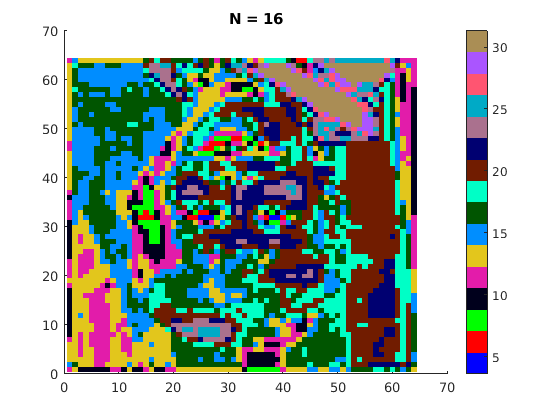

%% Step 4 (no template): Assign maximally different colors to the block
nameoption = 1;% 1: random colors, 3: using a color template

[CWro,SortConsRO] = assign_network_colors(sorted_clusters,nameoption); % make sure here you used "sorted_clusters" if you use "example_clusters" which was not sorted it won't work



% Now CWro is a structure with two fields, "Nets" and "cMap"
% where Nets is the name of the clusters, right now just 1 to n_unique_clusters, 
% cMap is the colormap of each cluster n_unique_clusters x 3 [R G B] each
% value is between 0 and 1

% SortConsRO is the reordered networks such that similar names will be
% ordered together and the order is consistent with the order of template
% (see below)

% You may wish to it now so next time we can start with step 3
save('./Results/example_results.mat','SortConsRO','CWro');

%% Step 5 (with template): Assign colors with a CIFTI template (when the node is surface parcels)
% N.B. this needs cifti-matlab-master to be on the path (included at
% ./ExternalFunctions)
nameoption = 3;% 1: random colors, 3: using a color template
templatepath  ='./Templates/Gordon2017_17Networks.dlabel.nii'; % replace with your template path, some are provided in ./Templates, it has to be a .dlabel.nii file to get the network names
parcelpath = './Parcels/Gordon333.dtseries.nii' % replace with your parcel path, data size should match exactly with the template path

parcelpath = './Parcels/Gordon333.dtseries.nii'

% dice similarity to network
Network 1: SM Foot, SM Foot = 0.39 , Dorsal SM = 0.32 , Ventral SM = 0.29 ,
Network 2: Med Temporal, Med Temporal = 0.37 , Parieto-occipital = 0.14 , Med Temporal 2 = 0.14 ,
Network 3: Auditory, Auditory = 0.46 , Ventral Attention = 0.22 , Cingulo-opercular = 0.02 ,
Network 4: Cingulo-opercular, Cingulo-opercular = 0.54 , Dorsal Attention = 0.19 , Pre-motor = 0.06 ,
Network 5: Medl Visual, Medl Visual = 0.53 , Visual = 0.41 , Dorsal Attention = 0.05 ,
Network 6: unclassified, Fronto-parietal = 0.09 , Ventral Attention = 0.00 , Cingulo-opercular = 0.00 ,
Network 7: Dorsal Attention, Dorsal Attention = 0.54 , Fronto-parietal = 0.15 , Cingulo-opercular = 0.10 ,
Network 8: Default, Default = 0.71 , Parieto-occipital = 0.06 , Ventral Attention = 0.06 ,
Network 9: Fronto-parietal, Fronto-parietal = 0.27 , Med Parietal = 0.16 , Cingulo-opercular = 0.13 ,
Network 10: unclassified, Med Temporal = 0.08 , Medl Visual = 0.07 , Parieto-occipital = 0.04 ,
Network 11: Vis

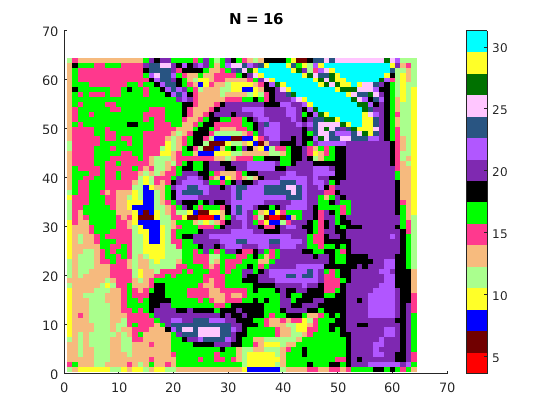

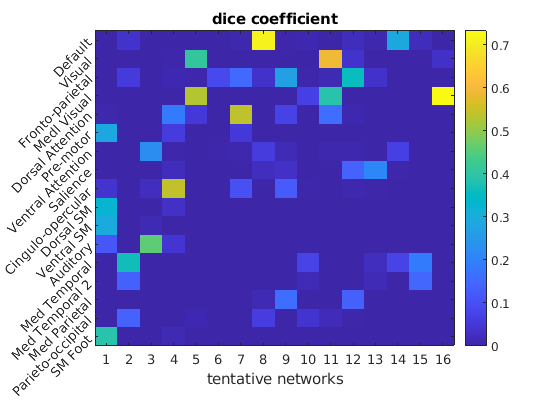


[CWro,SortConsRO] = assign_network_colors(sorted_clusters,nameoption,templatepath,parcelpath);


% You may wish to it now so next time we can start with step 4
save('./Results/example_results.mat','SortConsRO','CWro');


%% Step 6: Visualize the colors on the brain 
load('./Results/example_results.mat','SortConsRO','CWro'); % we are loading the sorted communites above
load('./Parcels/Parcels_Gordon.mat','Parcels');% load the "Parcels_*.mat" file that corresponds to your parcelpath above
levels = 1:size(SortConsRO,2); % replace if you have any meaningful value for the levels, e.g. the number of communities, the resolution parameter etc.
file_exten = './consensus_' % for saving the picture, replace with your saving path

file_exten = './consensus_'

Press on the block to switch between levels
, and press q for quit and s for saving figures when the mouse press is outside the blocks


Figure saved as ./consensus_68.000.png


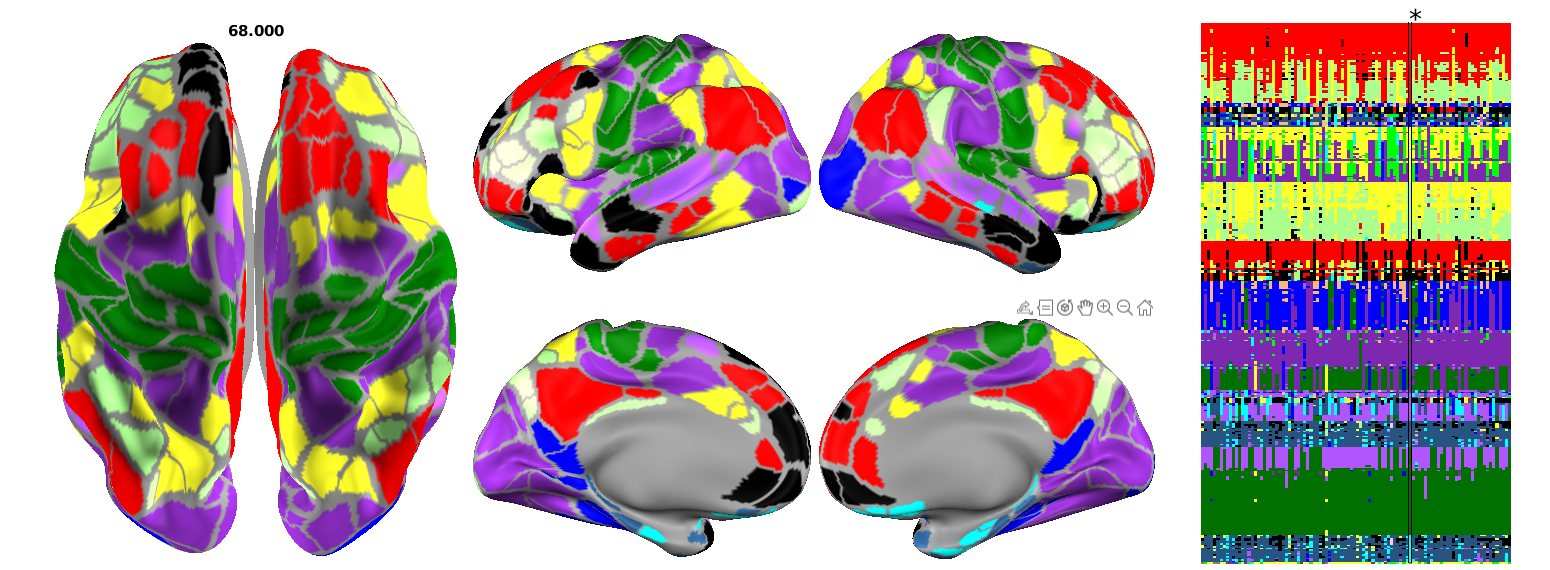


Explore_parcel_levels_HSB(SortConsRO,CWro.cMap,Parcels,levels,file_exten);


% The function above is an interactive plot for the different levels
% Press colormaps (the block on the right) to switch levels
% , and press q for quit and s for saving figures when the mouse press is outside the colormaps
